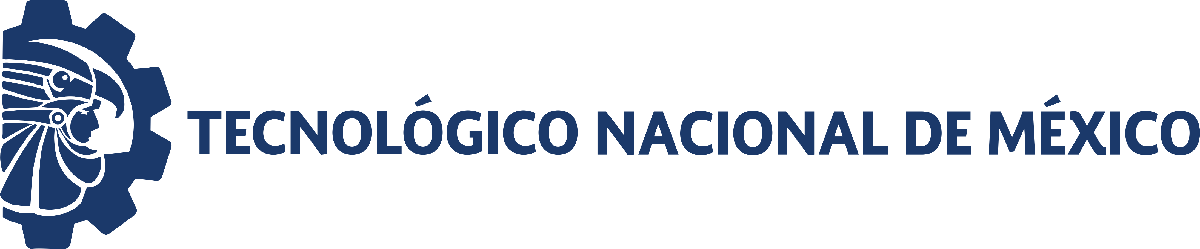                                 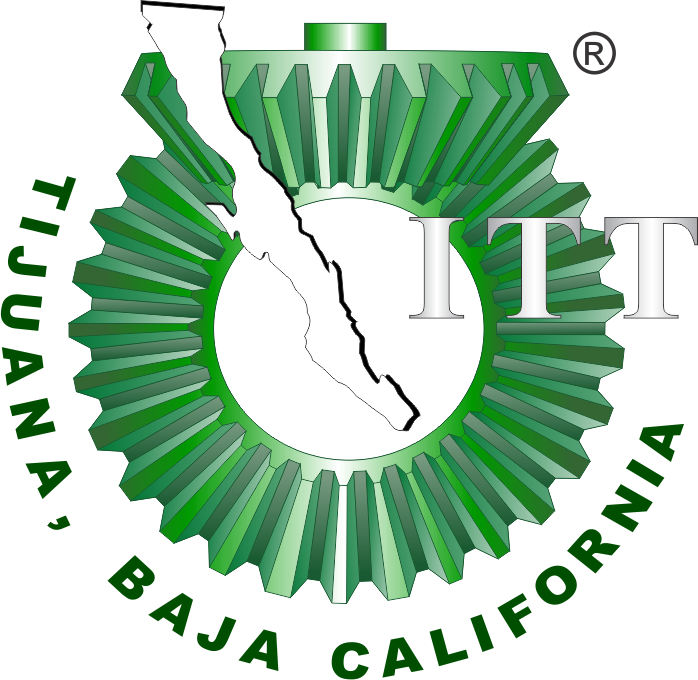

# Práctica cero: Mecánica pulmonar

Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

**Table of Contents**

Datos de la simulación 

Rendimiento del controlador

Respiracion Normal

Respiracion Anormal

Funcion: Respuesta a las señales

## Mecanica Pulmonar

##                                                                   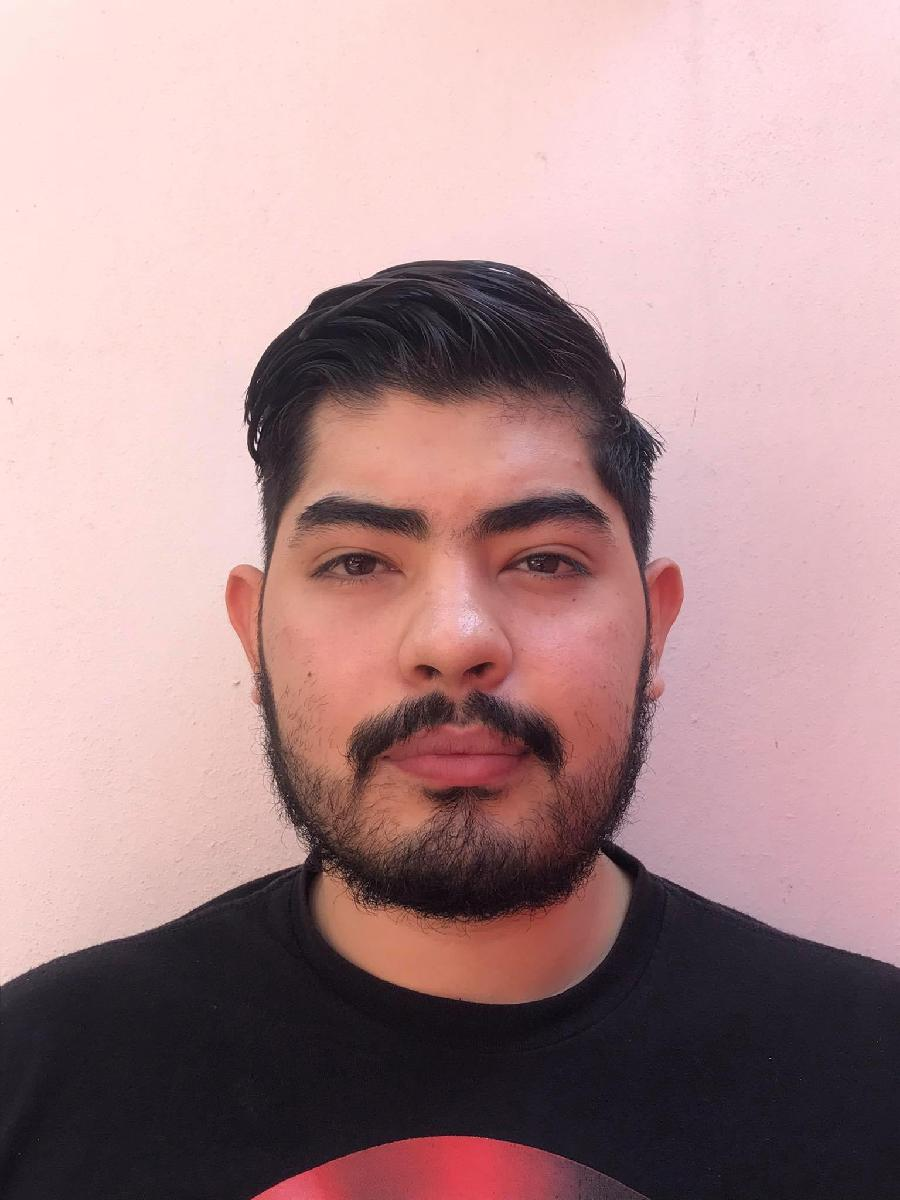                                           

Nombre del alumno: Dario Antonio Martinez Camarena

Número de control: 21210684

Correo institucional: l21210684**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación 

clc; clear; close all; warning('off','all')
tend= '10';
file= 'Respiracion.slx';
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
parameters.StopTime = '30';

## Rendimiento del controlador

kP = 13126.69;

kl = 765802.31;

kD = 49.99;

Settlingtime = '0.0003';

overshot = '0.312' ;

peak = '1';

## Respiracion Normal

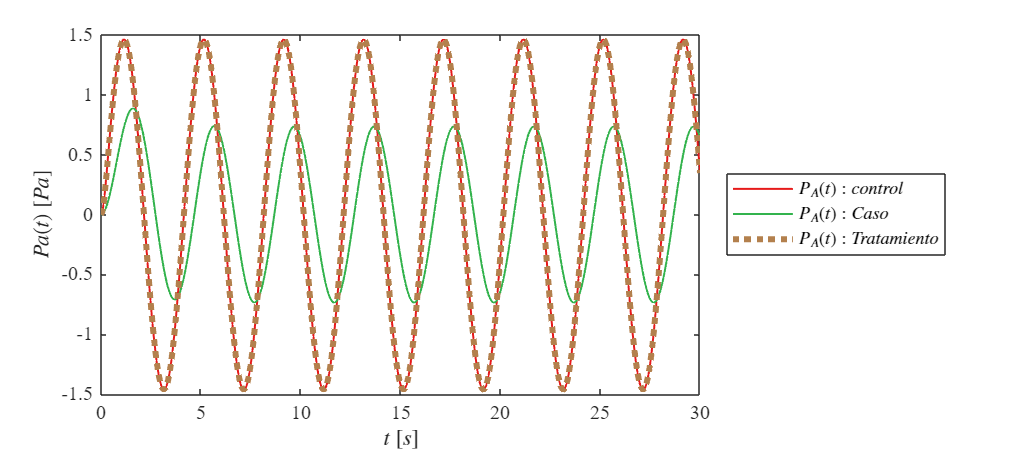

 
Signal = 'Respiracion normal';
set_param('Respiracion/Pao(t)','sw','0');
set_param('Respiracion/PID Controller','P','1511.4945');
set_param('Respiracion/PID Controller','I','74979.6737');
set_param('Respiracion/PID Controller','D','7.0888');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiracion Anormal

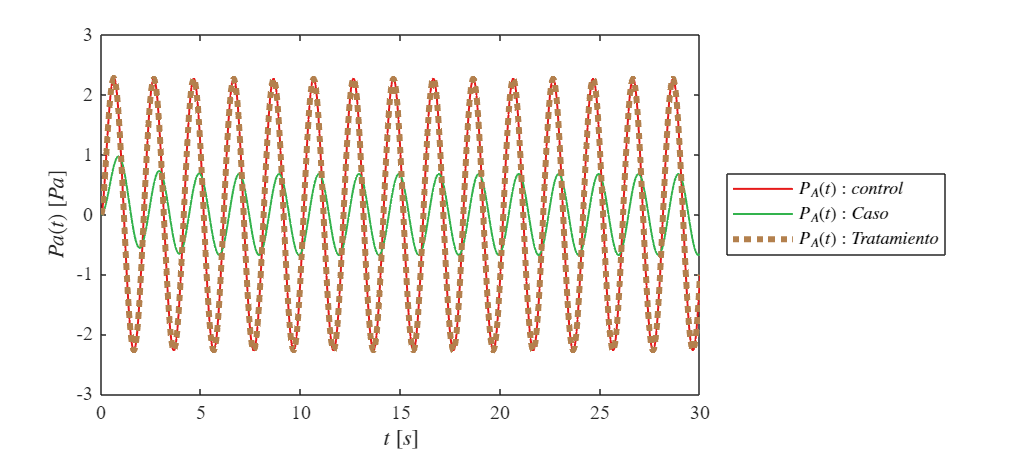

Signal = 'Respiracion anormal';
set_param('Respiracion/Pao(t)','sw','1');
set_param('Respiracion/PID Controller','P','1511.4945');
set_param('Respiracion/PID Controller','I','74979.6737');
set_param('Respiracion/PID Controller','D','7.0888');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Funcion: Respuesta a las señales

function plotsignals (t,PA,Pao,PID)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    RED =  [0.9, 0.1, 0.1];
    GR = [0.2, 0.7, 0.3] ; 
    BR = [0.7, 0.5, 0.3];
    hold on ; grid off; box on

    plot(t,PA,'LineWidth',1,'Color',RED)
    plot(t,Pao,'LineWidth',1,'Color',GR)
    plot(t,PID,':','LineWidth',3,'Color',BR)

    xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$Pa(t)$ $[Pa]$','Interpreter','Latex')

    L = legend('$P_{A}(t): control$','$P_A(t): Caso$','$P_{A}(t): Tratamiento$');
    set(L,'Interpreter','Latex','Location','EastOutside','Box','on')

   
end

